clc 
clear
runTime=2.5; %Tiempo que dura la simulacion de Simulink

### Periodo de Muestreo

Ts=25/1000; %buscamos un Ts que haga que Pd sea inversamente estable
ts=Ts;

### Modelo de Planta

%%Modelado
s=tf('s');
z=tf('z', Ts);
P = 0.020/(1+0.050*s)/(1+0.2*s)

P =
 
          0.02
  ---------------------
  0.01 s^2 + 0.25 s + 1
 
Continuous-time transfer function.



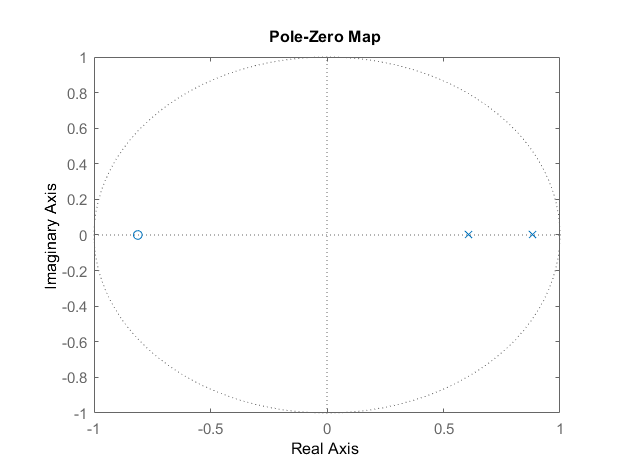

Pd=c2d(P, Ts, 'zoh');
pzmap(Pd)% O dentro del circulo unidad -> estable

delay = exp(-ts*s/2);
Pm = P*delay;

### 2 CONTROL P

### 2.1 P – DISEÑO

Fm=50

Fm = 50

Modelo analógico puro.

Fa = tf(1,1);
% calculamos valores de corte
wo_p = fsolve(@(wo) -180+Fm-180/pi*angle(freqresp(P,wo)),1);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Ap = abs(freqresp(P, wo_p));
Kp = 1/Ap;

% declaramos el control proporcional. K -> C
K = Kp

K = 407.6232

C = tf(K,1);
Cr = C;
Cd = c2d(C,ts,'zoh');
Crd = Cd;

## 2.2 P – ANÁLISIS

%analogico modificado

Fa = tf(1,1);
% calculamos valores de corte
wo_p = fsolve(@(wo) -180+Fm-180/pi*angle(freqresp(P,wo)),1);%OJO


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Ap = abs(freqresp(Pm, wo_p));
Kp = 1/Ap;
% declaramos el control proporcional. K -> C
K = Kp

K = 407.6232

C = tf(K,1);
Cr = C;
Cd = c2d(C,ts,'zoh');
Crd = Cd;
G_p=minreal(C*Pm);
% Margenes de estabilidad
[Am_p,Fm_p,wu_p,wo_p] = margin(G_p)%[reales,deg, rad,rad]

Am_p = 2.5783

Fm_p = 32.1090

wu_p = 43.5638

wo_p = 24.9806

% Sensibilidad
S_p=minreal(1/(1+G_p));

1 state removed.


% Pulsacion de maxima sensibilidad[rad/s]
ws_p=fminsearch(@(w) -abs(freqresp(S_p,w)),1)

ws_p = 30.4893

% Maxima sensibilidad[db]
Ms_p=20*log10(abs(freqresp(S_p,ws_p)))

Ms_p = 7.6912

% Funciones de transferencia de lazo cerrado
F_ry_p=minreal(C*Pm/(1+C*Pm));

1 state removed.


F_ru_p=minreal(Cr/(1+G_p));

1 state removed.


F_dy_p=minreal(-P/(1+G_p));

1 state removed.


F_du_p=minreal(Pm*C/(1+G_p));

1 state removed.



% Pulsacion de resonancia[rad/s]
wr_p=fminsearch(@(w) -abs(freqresp(F_ry_p,w)),1)

wr_p = 27.5422

% Pico de resonancia[db]
Mr_p=20*log10(abs(freqresp(F_ry_p,wr_p)))-20*log10(dcgain(F_ry_p))

Mr_p = 6.6124

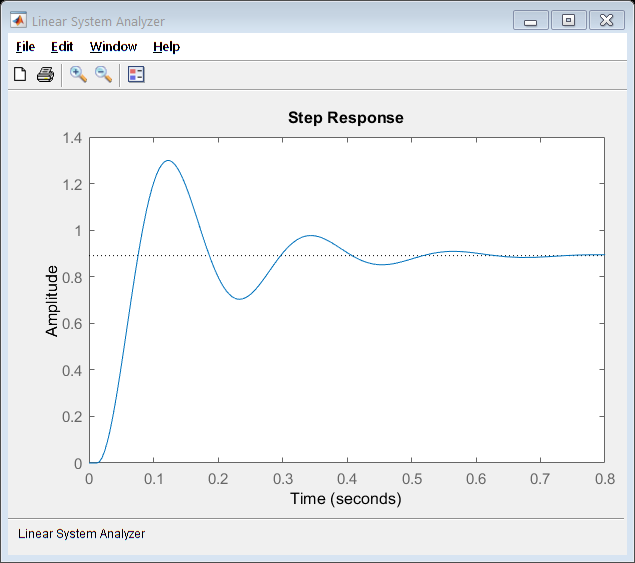



%black lazo abierto estabilidad Fm y Am
%ltiview(G_p)
%bode lazo abbierto margen de ganancia en db
%ltiview(G_p)
%bode lazo salida 
%ltiview(S_p) %pulsacion maxima sensibiliad
%ltiview(F_ry_p) % maxima resonanca ojo db desde perm no 0db

%escalones
ltiview(F_ry_p)%modificar el tiempo de estab al 5%